# Adaptive Airfoil Dynamics

clear; close; clc;

## Define variables

% Inertial constants
I_h = 1; % moment of inertia of flap about hinge (kg * m^2 / m)

% Spring constants
k = 2; % torsional spring constant of flap (N/rad)
delta_0 = deg2rad(10); % unloaded trailing edge deflection (rad)

% desired c_l_alpha
c_l_alpha_desired = 40*pi

c_l_alpha_desired = 125.6637


% Damping coefficient
c_r = 10 % rate damping coefficient (N*s/rad^2)

c_r = 10

c_c = 2 % colombic damping coefficient (N)p

c_c = 2

c_c_s = c_c - .1*c_c; % static coulmbic damping coefficient

% Stop spring range and coeffcient
delta_min = -deg2rad(20); % minimum deflection angle (radians)
delta_max = deg2rad(20); % maximum deflection angle (radians)
k_stop = 1000; % deflection limiting hardening spring stiffness N/(m^2)

% location of Flap 
r_f_i = [0; -1; 0]; % distance in body coordinates from the aircraft centre of gravity to the left most section of the control surface hingeline (m)
r_f_o = [0; 1; 0]; % distance in body coordinates from the aircraft centre of gravity to the right most section of the control surface hingeline (m)
r_f_i_TE = [-1; -1; 0]; % distance in body coordinates from the aircraft centre of gravity to the trailing edge of the left most section of the undeflected control surface (m)
r_f_cg_B = [0; 0; 0]; % distance in body coordinates from the aircraft centre of gravity to the location of the hingleline at the section of flap contining its centre of gravity (m)

% Aerodynamic variables and coefficients
c = 1; % cord (m)
c_f = .25 % flap cord (m)

c_f = 0.2500

C_h_0 = 0; % 0 angle of attack 0 deflection hinge moment (~)
C_h_alpha = -.45; % control surface hinge moment deriveative due to angle of attack (~)
C_h_delta = -.85; % control surface moment derivative due to flap deflection (~)

% aircraft coefficients
c_l_alpha_wf = 2*pi; % lift coefficient of wing fuselage combination per radian (1/radian)
c_l_alpha_h = 2*pi; % lift coefficient of wing fuselage combination per radian (1/radian)
tau_delta_f = .45; % efficiency of flap (~) from roskam stability and control part 1 page 61 figure 2.23
eta_h = .9; % dynamic pressure ratio of horizontal tail to free stream (~)
S_h = 1.75; % horizontal tail planform area (m^2)
S = 13.27; % wing planform area (m^2)
d_elpsilon_d_alpha_h = .111; % downwash gradient on the horizontal tail (1/radians) from AAA (can also compute using roskam part 6 page 262)


% flihgt parameters
rho = 1.225; % atmpospheric density (kg/m^3)
alpha = deg2rad(2); % angle of attack (radians)
u_B = 30;
V_a_B = [u_B; 0; u_B*tan(alpha)]; % velocity relative to airmass in body coordinates (equal to aircraft velocity in body coordinates is win is zero) (m/s)
omega_B = [0,0,0]; % aircraft angular rates in body coordinates (radians/second)


% TODO: implement hinge moment

% initial conditions
theta_0 = deg2rad(-10); % initial angle (radians) - positive TE down
omega_0 = 0; % initial angular velocity (radians/second) - positive TE down

% simulation settings
tspan = 5; % simulation time (seconds)
delta_disp = deg2rad(20); % range of angles to display in phase space plot (radians)
deltaDot_disp = deg2rad(20); % range of anglular velocities to display in phase space plot (radians/s)
n_points_plot = 250; % number of points to disply in phase space plot



## Good airfoil properties

% set k for constant lift flight (via delta alpha)
q_bar = 1/2 * rho * norm(V_a_B)^2; % dynamic pressure (Pa)

% % find required derivative of steady-state flap defection w/ respect to alpha
% partial_delta_star_partial_alpha = (1/tau_delta_f) * (1 + (eta_h * S_h/S * c_l_alpha_h * (1-d_elpsilon_d_alpha_h)) / c_l_alpha_wf) % this assumes c_l_alpha = c_L_alpha
% % compute k at given flight conditions using derivative obtained above
% k = q_bar * c_f^2 * (C_h_alpha / partial_delta_star_partial_alpha + C_h_delta)



% set c_r for airfoil responce properties
zeta = .7; % damping ratio

mu = 4*I_h* (q_bar * c_f^2 * C_h_delta - k) % airfoil responce parameter

mu = -125.2835


% set damping to make that true (note culombic damping will be suboptimal
c_d = 2*I_h*zeta * sqrt(-mu * (2*I_h*zeta - 1) * (2*I_h*zeta + 1)) / (4*I_h^2*zeta^2-1) % total damping coefficient

c_d = 15.9933

% unsure if i should use the one that acounts for culombic damping (good
% near fp) or the one that doesn't (good far from f.p.) I think that as
% this is transient responce culombic damping should be acounted for
c_r = max(c_d - c_c,0) 

c_r = 13.9933

%c_r = c_d

## Configure simulation

% simulation parameters
y_0 = [theta_0, omega_0]; % Initial state
tspan = [0 tspan];

% physics parameters


## Airfoil Dynamics

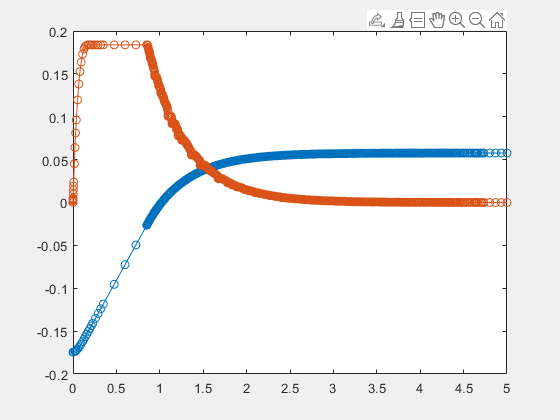

% Simulate airfoil
% for now asssume detla_0 is not a function of time
% state vector y = [theta; theta']
%ode45(@(t,y) Adaptive_Airfoil_Dynamics(t, y, I_h, k, delta_0, c_r, c_c, c_f, C_h_0, C_h_alpha, C_h_delta, alpha, q_bar), tspan, y_0);

% new one
ode45(@(t,y) Adaptive_Aerocompliant_Airfoil_Dynamics(t, y, I_h, k, delta_0, c_r, c_c, c_f, C_h_0, C_h_alpha, C_h_delta, delta_min, delta_max, k_stop, r_f_i, r_f_o, r_f_i_TE, r_f_cg_B, rho, V_a_B, omega_B), tspan, y_0);

%ode45(@(t,y) Adaptive_Aerocompliant_Airfoil_Dynamics(t, y, I_h, k, delta_0, c_r, c_c, c_f, C_h_0, C_h_alpha, C_h_delta, delta_min, delta_max, k_stop, r_f_i, r_f_o, r_f_i_TE, r_f_cg_B, rho, V_a_B, omega_B), tspan, y_0);

% Determine system dynamics
omega_n = sqrt((k + q_bar * c_f^2 * C_h_delta)/I_h) % natural frequency

omega_n = 0.0000 + 5.2269i

lambda = -(1/(2*I_h)) * [c_r^2 + sqrt(c_r^2+mu); c_r^2 - sqrt(c_r^2+mu)]

lambda =  -102.1060
  -93.7077


tau = (real(lambda)./imag(lambda)).^-1

tau =      0
     0


tau = 1./(-lambda)

tau =     0.0098
    0.0107


## Plot Phase Space

delta_grid = linspace(-delta_disp, delta_disp, floor(sqrt(n_points_plot)));
deltaDot_grid = linspace(-deltaDot_disp, deltaDot_disp, floor(sqrt(n_points_plot)));
[phase_grid(:,:,1), phase_grid(:,:,2)] = meshgrid(delta_grid, deltaDot_grid);

phase_space = zeros(size(phase_grid,1), size(phase_grid,2), 2);


for i = 1:size(phase_grid,1)
    for j = 1:size(phase_grid,2)
        delta = phase_grid(i,j,1);
        deltaDot = phase_grid(i,j,2);
        phase_space(i,j,:) = Adaptive_Aerocompliant_Airfoil_Dynamics(1,[delta, deltaDot], I_h, k, delta_0, c_r, c_c, c_f, C_h_0, C_h_alpha, C_h_delta, delta_min, delta_max, k_stop, r_f_i, r_f_o, r_f_i_TE, r_f_cg_B, rho, V_a_B, omega_B);
    end
end

figure
contourf(phase_grid(:,:,1), phase_grid(:,:,2), sqrt(phase_space(:,:,1).^2 + phase_space(:,:,2).^2), 50, "-", "EdgeColor","none"); colormap("spring"); colorbar;
hold on;
quiver(phase_grid(:,:,1), phase_grid(:,:,2), phase_space(:,:,1), phase_space(:,:,2),"Color", [0,0,0], "LineWidth",2);
xlabel("Flap Delfection, $\delta_f$, (rad)", Interpreter="latex", FontSize=12);
ylabel("Rate of Flap Delfection, $\dot{\delta_f}$, (rad/s)", Interpreter="latex",FontSize=12);
%title("Phase Portrait of Aerocompliant Flap", "Interpreter","latex", "FontSize",15);
xlim([min(phase_grid(:,:,1),[],"all"), max(phase_grid(:,:,1),[],"all")]);
ylim([min(phase_grid(:,:,2),[],"all"), max(phase_grid(:,:,2),[],"all")]);
set(gca,"LineWidth",2);
cb = colorbar; ylabel(cb,'Gradient Magnitude, $\sqrt{\ddot{\delta}^2 + \dot{\delta}^2}$', "Interpreter","latex", 'FontSize',12,'Rotation',270);

% figure displays in radians we need to relable into degrees
ax = gca;
current_ticks = xticks; % get the current labels
new_labels = arrayfun(@(label) sprintf('%.0f°', rad2deg(label)), current_ticks, 'UniformOutput',false) % rename current lables to degrees

new_labels = 1×7 cell array
    {'-17°'}    {'-11°'}    {'-6°'}    {'0°'}    {'6°'}    {'11°'}    {'17°'}


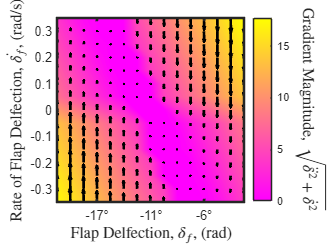

ax.XTickLabel = new_labels; % apply the degree lables



% make one just to show hardening spring
figure
HM_hs = -k_stop * ((heaviside(delta_min - phase_grid(:,:,1)) .* (phase_grid(:,:,1) - delta_min)) +  (heaviside(phase_grid(:,:,1) - delta_max) .* (phase_grid(:,:,1) - delta_max)))

HM_hs =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



contourf(phase_grid(:,:,1), phase_grid(:,:,2), HM_hs)


xlabel("Flap Delfection, $\delta_f$, (rad)", Interpreter="latex", FontSize=12);
ylabel("Rate of Flap Delfection, $\dot{\delta_f}$, (rad/s)", Interpreter="latex",FontSize=12);
%title("Phase Portrait of Aerocompliant Flap", "Interpreter","latex", "FontSize",15);
xlim([min(phase_grid(:,:,1),[],"all"), max(phase_grid(:,:,1),[],"all")]);
ylim([min(phase_grid(:,:,2),[],"all"), max(phase_grid(:,:,2),[],"all")]);
set(gca,"LineWidth",2);
cb = colorbar; ylabel(cb,'Gradient Magnitude, $\sqrt{\ddot{\delta}^2 + \dot{\delta}^2}$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
ax = gca;
current_ticks = xticks; % get the current labels
new_labels = arrayfun(@(label) sprintf('%.0f°', rad2deg(label)), current_ticks, 'UniformOutput',false) % rename current lables to degrees

new_labels = 1×7 cell array
    {'-17°'}    {'-11°'}    {'-6°'}    {'0°'}    {'6°'}    {'11°'}    {'17°'}


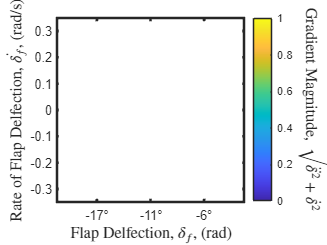

ax.XTickLabel = new_labels; % apply the degree lables

function dydt = Adaptive_Airfoil_Dynamics(t, y, I_h, k, delta_0, c_r, c_c, c_f, C_h_0, C_h_alpha, C_h_delta, alpha, q_bar)
    %TODO: include inertial forces if offset cg

    % unpack the state variable
    delta = y(1); % angular position (rad) positive TE down
    omega = y(2); % angular velocity (rad/s) positive TE down
    
    % compute derivative of angle
    delta_dot = omega;

    % compute hinge moment (Roskam aircraft design part 6 pages 463-477)
    M_h = q_bar * c_f^2 * (C_h_0 + C_h_alpha * alpha + C_h_delta * delta); % 2D hinge moment (N*m/m)

    omega_dot = 1/(I_h) * ( -k*(delta - delta_0) - c_r*omega - c_c*(heaviside(omega)-heaviside(-omega)) + M_h) * heaviside(abs(-k*(delta - delta_0) - c_r*omega + M_h) + c_c);

    % TODO: clamp omega dot to zero if force of culombic dominates
    % statically
    
    % return the derivatives
    dydt = [delta_dot; omega_dot];
end